# Discrete Fourier Transform

**Learning Goals**

- <LO 1>

- <LO 2>

While Fourier series and Fourier transforms are useful for learning about the mathematics of the frequency domain (among other applications), there's really one essential tool for signal analysis: the *Discrete Fourier Transform *(DFT). You'll often find this under a different name: the FFT (Fast Fourier Transform). Don't be confused, though, they're fundamentally the same. The FFT is simply an algorithm that computes the DFT, you guessed it, faster.

## Definition

The DFT is similar to the complex Fourier series and Fourier Transform. The essential difference is that it defines the transform of a discrete sequence of $N$ complex numbers: $\{ y_n \}$, rather than a continuous function. The DFT is defined as


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


The result is a sequence of $N$discrete values $\{ Y_k \}$ that represent $\{ y_n \}$ in the frequency domain. The result $\{ Y_k \}$ is analagous to the Fourier transform of a function $\hat{y}(\omega)$, but more on that later.

## Computing the DFT

 **Example.** In this example, the DFT is computed directly from the definition.

**Task.** First, create the data points by running this section.

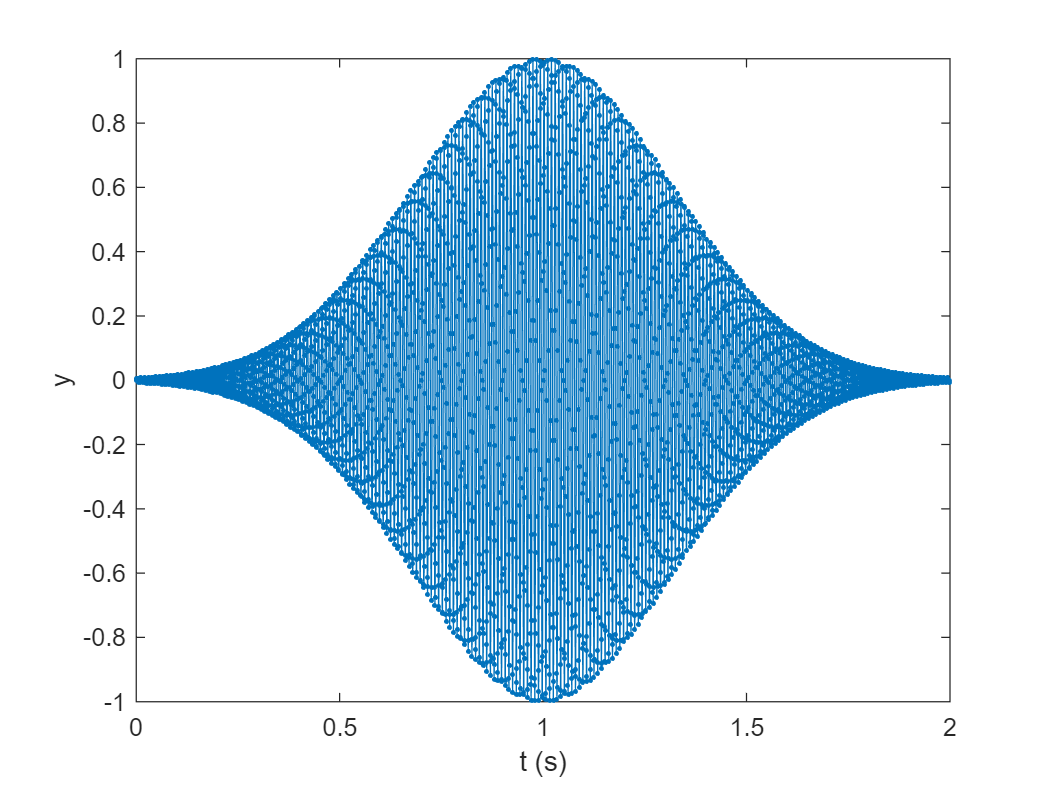

Fs = 2e3; % Audio sample rate
t = 0:1/Fs:2; % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)
plot(t,y,'.-')
xlabel("t (s)")
ylabel("y")

Try zooming in on the signal to view the discrete data points $y_n$ that make up this digital audio signal.

**Task. **Run this section to play the generated signal as an audio clip.

% This code will play the audio signal
soundsc(y,Fs)

**Task. **Run this section to compute the DFT using the definition. Note that the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) functions are used to measure the amount of time required to compute the N-point DFT.

N = numel(y); % The number of samples in y
n = 0:(N-1); % Indices
% Loop through the indices of Yk
tic
for k = 0:(N-1)
    % Compute the sum and put the result in Y
    Y(k+1) = sum( y.*exp(-2*pi*1i*k*n/N) );
end
toc

Elapsed time is 0.188960 seconds.


**Task. **Run this section to plot the real and imaginary components of the result.

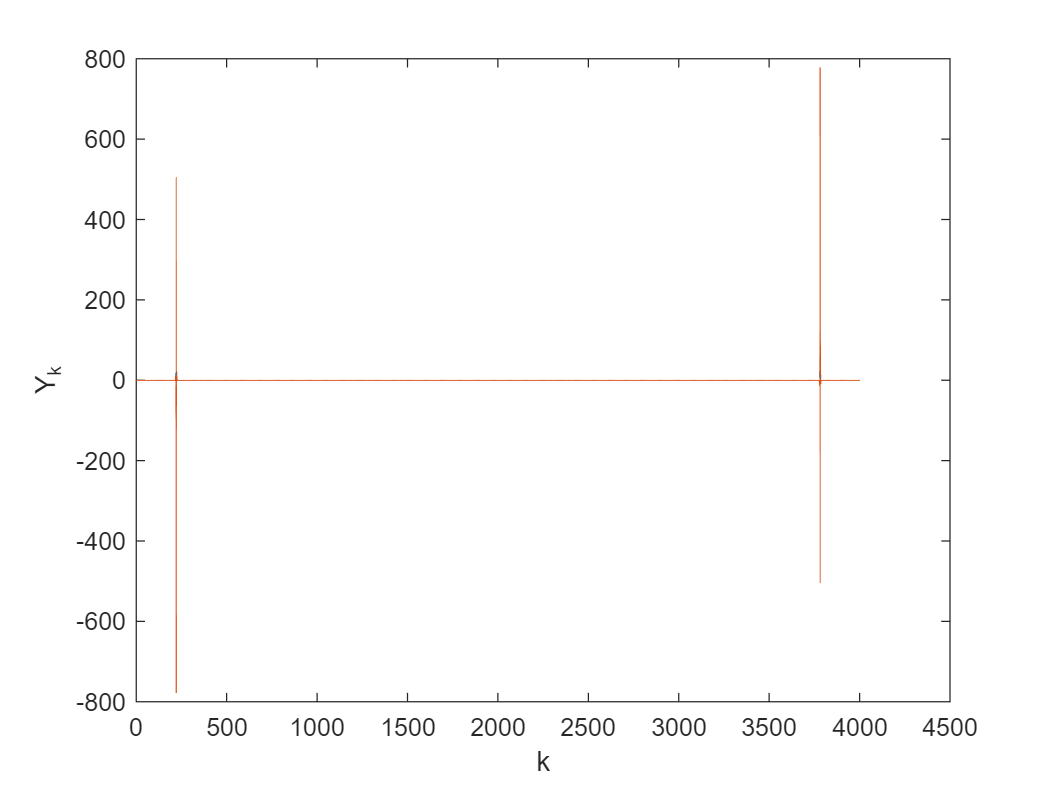

plot(real(Y))
hold on
plot(imag(Y))
hold off
xlabel("k")
ylabel("Y_k")

### Fast Fourier Transform (FFT)

In the previous example, the DFT was computed using a for loop, requiring $O(N^2)$ computations. This is very ineffecient relative to the Fast Fourier Transform (FFT). FFT algorithms break up the DFT into smaller DFTs, and then combine the results together to form the full DFT. The FFT requires only $O(N \log(N))$ operations. This implies the fft can be thousands of times faster than the DFT for large data sets.

 **Exercise.**  In this exercise, you will compute the DFT using the FFT algorithm.

**Task 1.** First, create the data points by running this section.

Fs = 2e3; % Audio sample rate
t = 0:1/Fs:2; % 2 second time variable
y = sin(2*pi*110*t).*exp(-5*(t-1).^2); % Sampled audio signal (Gaussian-modulated sinusoid)

**Task 2. **Use the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function to compute the DFT of `y` and store the result in Y.

% Write your code here
tic
Y = fft(y);
toc

Elapsed time is 0.001851 seconds.


**Task 3. **Surround the `fft` computation in **Task 2** with the [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) and [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) functions to measure how long it takes to compute the fft. Compare this to the amount of time required using the definition in the previous section.

**Task 4. **Plot the real and imaginary components of `Y`. To extract the real and imaginary components, use the [`real`](https://www.mathworks.com/help/matlab/ref/real.html) and [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) function. Use [`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) commands to continue plotting on the same axes.

% Write your code here
plot(real(Y))
hold on
plot(imag(Y))
hold off
xlabel("k")
ylabel("Y_k")

If correct, your result should be identical to the plot from the previous example.